# **整体优化**

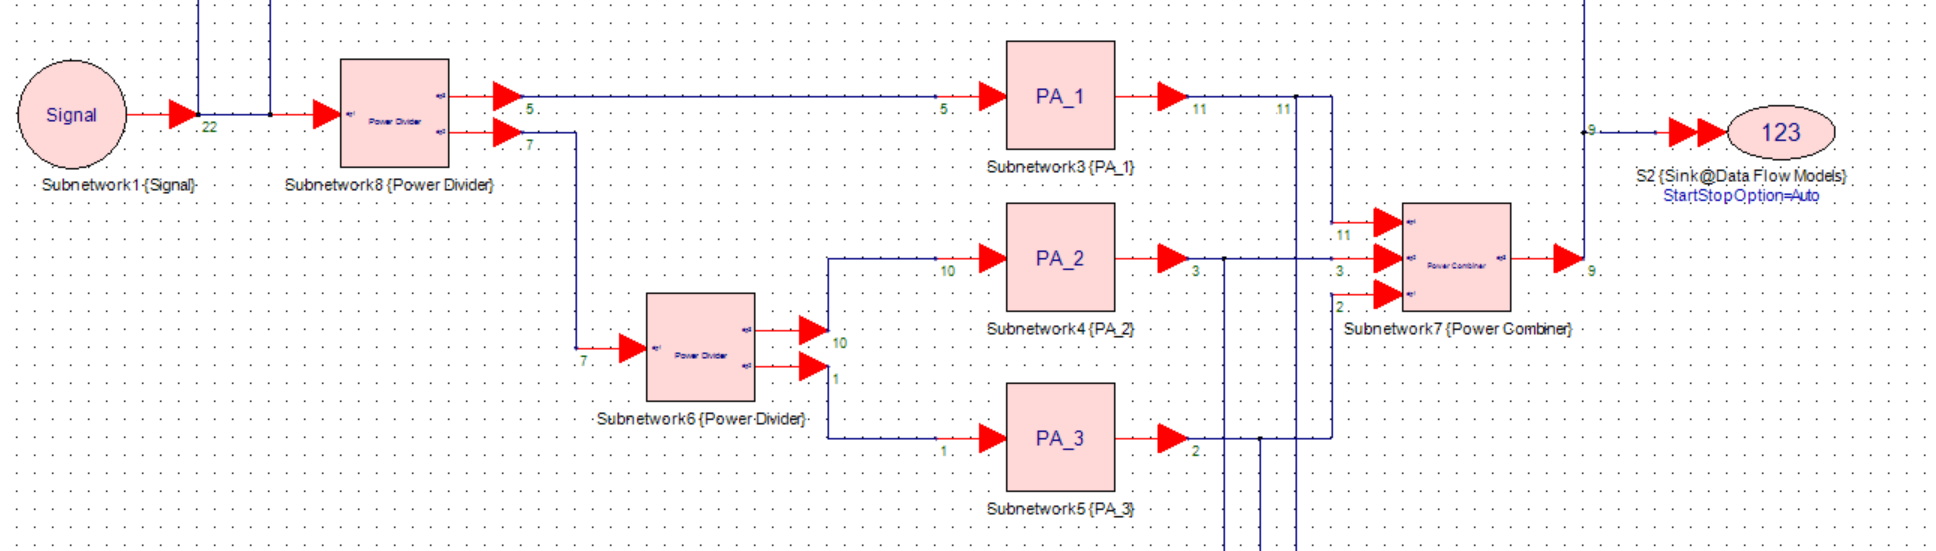

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model A Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Sys_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 参数需要保持一致
M = 0; 
path = 'Method_A\Whole\NN4.mat';

## 【训练】整体训练

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　　　１．２８　｜　　　　　　１．０９　｜　　０．８１６５　｜　０．５９２２　｜　　０．００３０　｜
｜　　２０　｜　　　２０　｜　　　　　００：００：１１　｜　　　　　　　０．１２　｜　　　　　　０．１１　｜　　０．００７０　｜　０．００６２　｜　　０．００３０　｜
｜　　４０　｜　　　４０　｜　　　　　００：００：２０　｜　　　　　　　０．０６　｜　　　　　　０．０６　｜　　０．００１８　｜　０．００１９　｜　　０．００３０　｜
｜　　５０　｜　　　５０　｜　　　　　００：００：２５　｜　　　　　　　０．０５　｜　　　　　　　　　　　｜　　０．００１３　｜　　　　　　　　｜　　０．００３０　｜
｜　　６０　｜　　　６０　｜　　　　　００：００：２９　｜　　　　　　　０．０５　｜　　　　　　０．０５　｜　　０．００１１　｜　０．００１３　｜　　０．００１５　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：３８　｜　　　　　　　０．０４　｜　　　　　　０．０５　｜　　０．０００９　｜　０．００１０　｜　　０．００１５　｜
｜　１００　｜　　１００　｜　　　　　００：００：４７　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００７　｜　０．０００９　｜　　０．００１５　｜
｜　１２０　｜　　１２０　｜　　　　　００：００：５６　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００６　｜　０．０００７　｜　　０

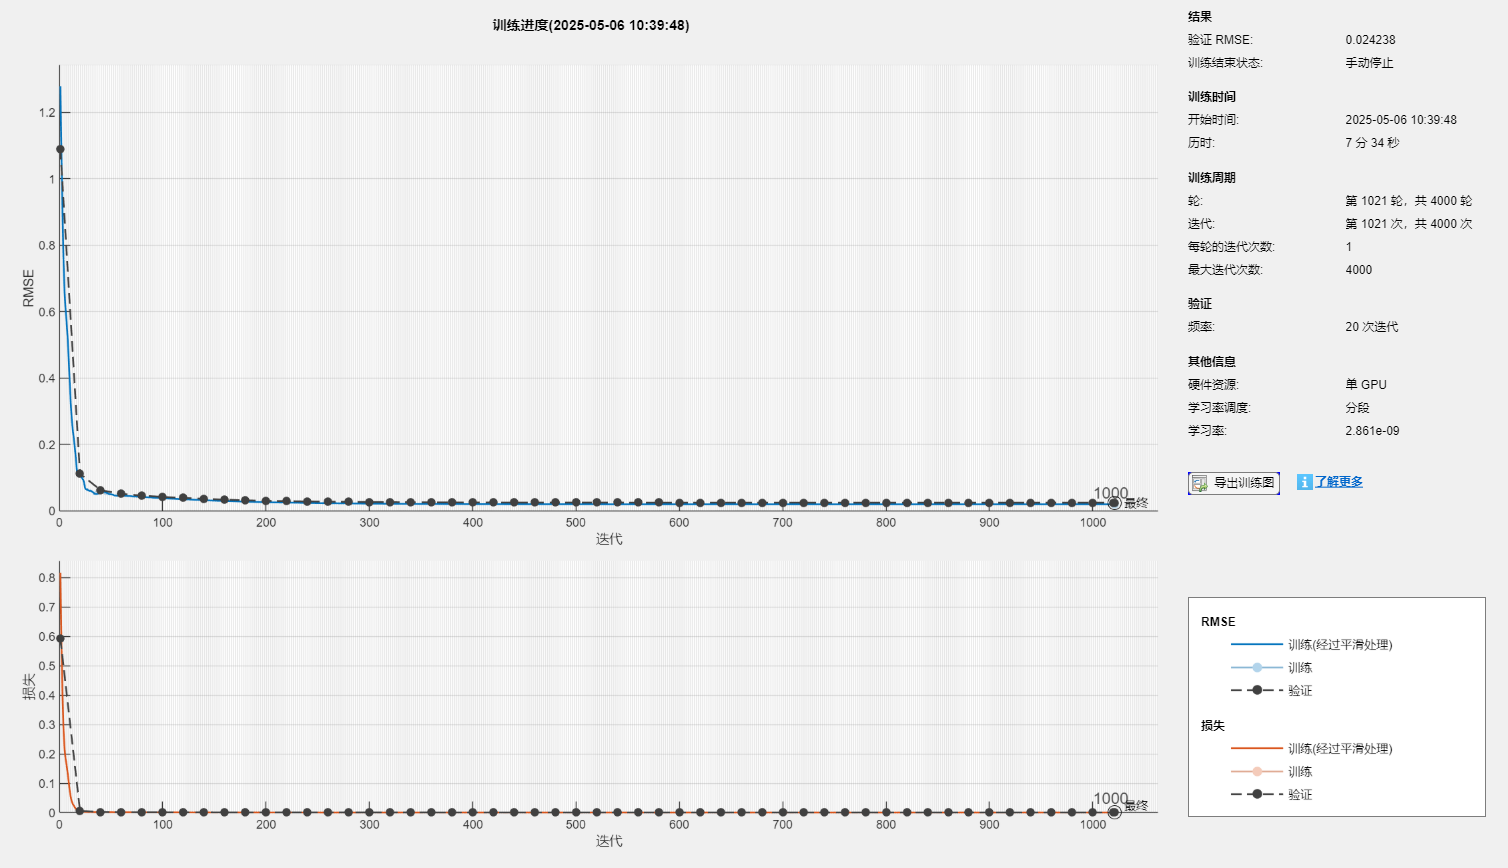

% 模型训练
model=Train_Whole(M,dim,Sys_input,Sys_output);

save(path, 'model');
% 模型精度
[model_input,model_output] = pre_train(M,Sys_input,Sys_output,dim);
data = load(path);
DPD_output_m = predict(data.model,model_input);
DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

模型的拟合精度NMSE为 -31.009338 dB


## Model Test

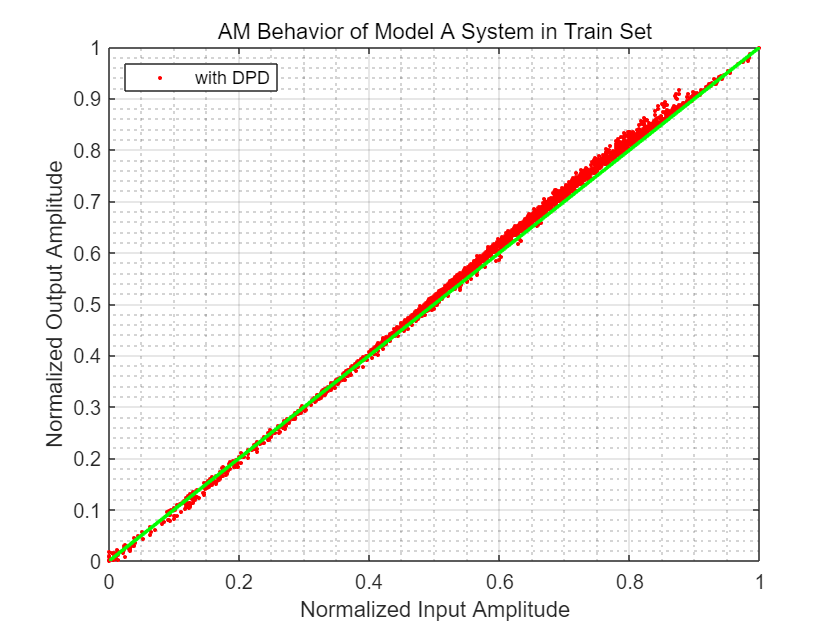

% 模型仿真
Sys_input_DPD=DPD_predict(Sys_input,M,path);
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Model A System in Train Set','with DPD');

nmse= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model A，系统的NMSE(Train)仿真结果为 %f dB\n', nmse);

使用Model A，系统的NMSE(Train)仿真结果为 -31.184969 dB


## -----------------------------Model A Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 0;
path = 'Method_A\Whole\NN4.mat';

## Model Test

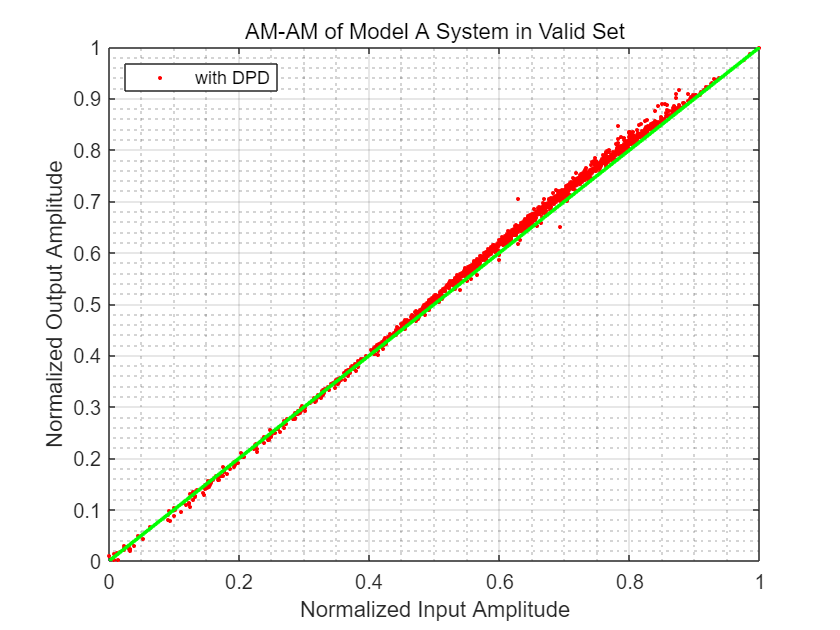

% 模型仿真
Sys_input_DPD=DPD_predict(Sys_input,M,path);
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+M）个值
Sys_input = Sys_input(5+M:end);
Sys_output = Sys_output(5+M:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM-AM of Model A System in Valid Set','with DPD');

nmse= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model A，系统的NMSE(Valid)仿真结果为 %f dB\n', nmse);

使用Model A，系统的NMSE(Valid)仿真结果为 -31.122194 dB
